tRange=[0,15]

tRange =      0    15


Y0=[156 0 0 0]

Y0 =    156     0     0     0


[tSol,YSol]=ode45(@neural,tRange,Y0)

tSol =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


YSol =   156.0000         0         0         0
  156.0000    0.0001         0         0
  156.0000    0.0001         0         0
  156.0000    0.0002         0         0
  156.0000    0.0002         0         0
  156.0000    0.0005         0         0
  156.0000    0.0007         0         0
  156.0000    0.0010         0         0
  156.0000    0.0012         0         0
  156.0000    0.0025         0         0



z1=YSol(:,1)

z1 =   156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000
  156.0000


z2=YSol(:,2)

z2 =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


z3=YSol(:,3)

z3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z4=YSol(:,4)

z4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



p=1.5

p = 1.5000

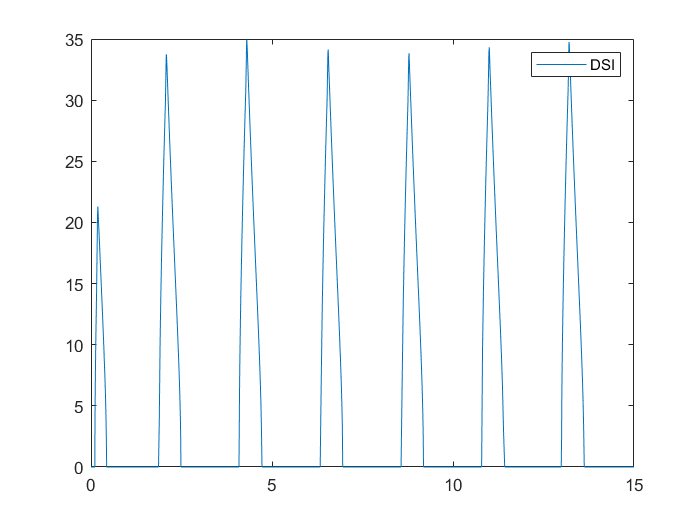

termin=-50+60;
a1=real(p.*sqrt((real(sqrt(z1)).^2).^2-termin.^2));
a2=real(p.*sqrt((real(sqrt(z2)).^2).^2-termin.^2));
a3=real(p.*sqrt((real(sqrt(z3)).^2).^2-termin.^2));
a4=real(p.*sqrt((real(sqrt(z4)).^2).^2-termin.^2));


plot(tSol,a2)
legend("DSI")

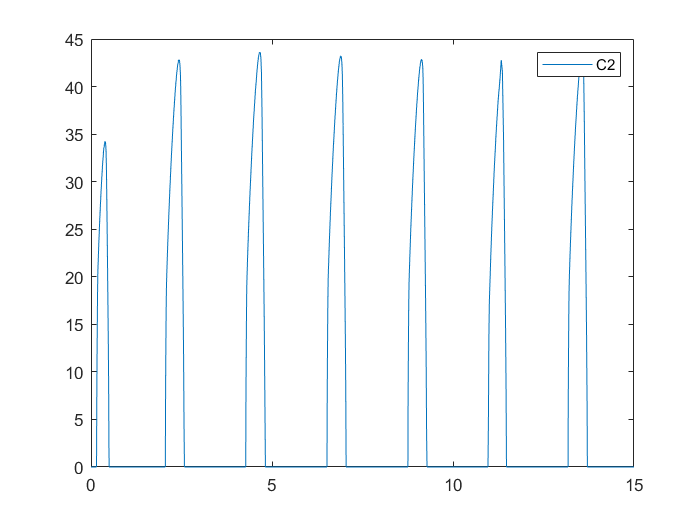

plot(tSol,a3)
legend("C2")

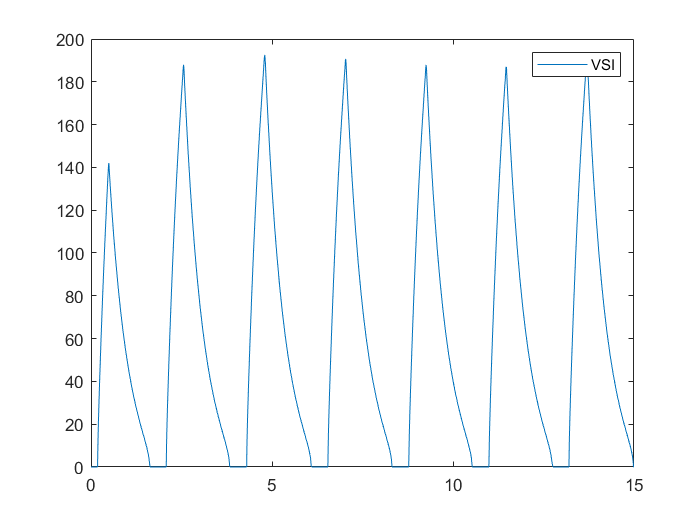

plot(tSol,a4)
legend("VSI")

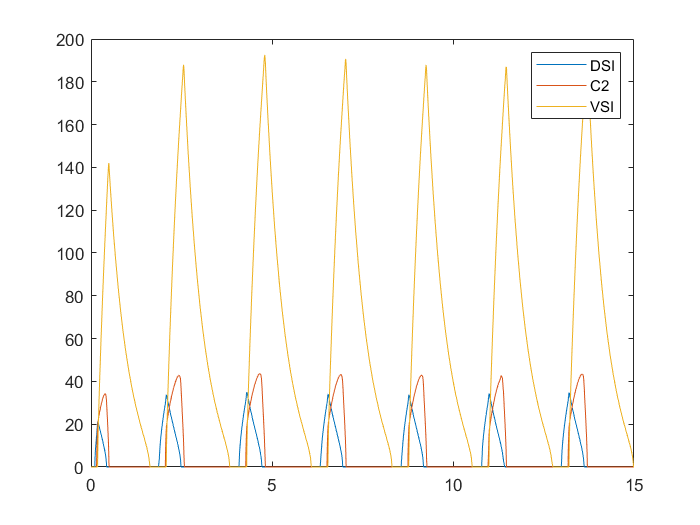

plot(tSol,a2)
hold on
plot(tSol,a3)
plot(tSol,a4)
hold off
legend("DSI","C2","VSI")

function dYdt=neural(~,Y)
z1=Y(1);
z2=Y(2);
z3=Y(3);
z4=Y(4);

termx=2+50;
termy=-50+70;
termin=-50+60;
p=1.25;

a1=real(p.*sqrt((real(sqrt(z1)).^2).^2-termin.^2));
a2=real(p.*sqrt((real(sqrt(z2)).^2).^2-termin.^2));
a3=real(p.*sqrt((real(sqrt(z3)).^2).^2-termin.^2));
a4=real(p.*sqrt((real(sqrt(z4)).^2).^2-termin.^2));

b1=(a1^2)/(2.83^2+a1^2);
b2=(a2^2)/(2.83^2+a2^2);
b3=(a3^2)/(2.83^2+a3^2);
b4=(a4^2)/(2.83^2+a4^2);


B=[b1;b2;b3;b4];

W1=termx.*[0 0 0 0]-termy.*[0 0 0 0];
W2=termx.*[1 0 0.5 0]-termy.*[0 0 0 4];
W3=termx.*[0 2.5 0 0]-termy.*[0 0 0 4];
W4=termx.*[0 0 4 0]-termy.*[0 0.5 0 0];

tao1=10000;
tao2=0.5;
tao3=0.5;
tao4=0.5;


dz1dt=(1/tao1)*(-z1+W1*B);
dz2dt=(1/tao2)*(-z2+W2*B);
dz3dt=(1/tao3)*(-z3+W3*B);
dz4dt=(1/tao4)*(-z4+W4*B);

dYdt=[dz1dt;dz2dt;dz3dt;dz4dt];
end
